# 62743 DSP — F24 Exam

% Full MATLAB Live Script for the F24 written exam
% ------------------------------------------------
% This script:
%  - Reproduces all calculations from the F24 exam solution markdown.
%  - Generates plots as PNG images for embedding into your Obsidian note.
%
% Image export folder (adjust if needed):
imgDir = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images';
if ~exist(imgDir, 'dir')
    mkdir(imgDir);
end

clearvars -except imgDir; close all; clc;


## Problem 1 — LTI Systems, Impulse Response and z-Domain

% Given:
% x1[n] = 3 δ[n] + 2 δ[n-1]
% x2[n] =   δ[n] + 2 δ[n-1]
%
% Table outputs (from exam statement):
%   n:   0    1    2    3    4
%  y1: [12  -28  -21   -7   -6]
%  y2: [ 4   -4  -23   -1   -6]

n_tab = 0:4;
y1 = [12 -28 -21 -7 -6];
y2 = [ 4  -4 -23 -1 -6];

fprintf('=== Problem 1 ===\n');

=== Problem 1 ===


## 1-1) x1[n] - x2[n]

% We work symbolically via delta-functions for understanding,
% but also check numerically over some n-range.

n = -2:3;
delta = @(k) double(k == 0);

x1 = 3*delta(n) + 2*delta(n-1);
x2 =    delta(n) + 2*delta(n-1);
xdiff = x1 - x2;

fprintf('\n1-1) x1[n] - x2[n]\n');


1-1) x1[n] - x2[n]


disp(table(n(:), x1(:), x2(:), xdiff(:), ...
    'VariableNames', {'n','x1','x2','x1_minus_x2'}));

    n     x1    x2    x1_minus_x2
    __    __    __    ___________

    -2    0     0          0     
    -1    0     0          0     
     0    3     1          2     
     1    2     2          0     
     2    0     0          0     
     3    0     0          0     



fprintf('As derived: x1[n] - x2[n] = 2 δ[n].\n');

As derived: x1[n] - x2[n] = 2 δ[n].


## 1-2) Impulse response h[n] = 0.5 (y1[n] - y2[n])

h = 0.5 * (y1 - y2);   % for n = 0..4

% We know the nonzero part is at n = 0..3; n=4 -> 0
n_full = -1:5;                 % show some zeros as well
h_full = zeros(size(n_full));
idx = ismember(n_full, n_tab);
h_full(idx) = h;

fprintf('\n1-2) Impulse response h[n]\n');


1-2) Impulse response h[n]


disp(table(n_tab(:), h(:), ...
    'VariableNames', {'n','h_n'}));

    n    h_n
    _    ___

    0      4
    1    -12
    2      1
    3     -3
    4      0



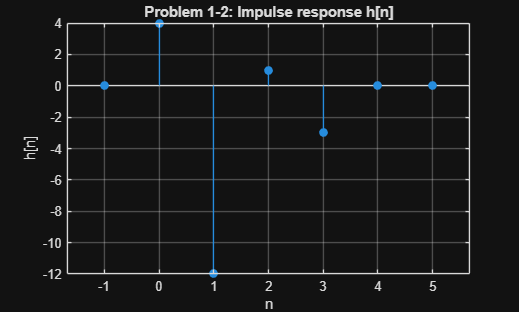


% Stem plot of h[n]
figure;
stem(n_full, h_full, 'filled'); grid on;
xlabel('n'); ylabel('h[n]');
title('Problem 1-2: Impulse response h[n]');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F24_1_ImpulseResponse.png'), 'Resolution', 300);

## 1-3) System function H(z)

% For a causal FIR with h[0..3] = [4 -12 1 -3]:
% H(z) = 4 - 12 z^{-1} + 1 z^{-2} - 3 z^{-3}

h_fir = h(1:4);   % [4 -12 1 -3]
B1 = h_fir;
A1 = 1;

fprintf('\n1-3) System function H(z)\n');


1-3) System function H(z)


fprintf('H(z) = 4 - 12 z^{-1} + 1 z^{-2} - 3 z^{-3}\n');

H(z) = 4 - 12 z^{-1} + 1 z^{-2} - 3 z^{-3}


## 1-4) Second LTI system: y[n] + (1/4) y[n-2] = x[n]

% H2(z) = 1 / (1 + 1/4 z^{-2})

B2 = 1;
A2 = [1 0 1/4];    % corresponds to 1 + 0*z^{-1} + (1/4)*z^{-2}

p2 = roots(A2);
z2 = roots(B2);

fprintf('\n1-4) Second LTI system H2(z)\n');


1-4) Second LTI system H2(z)


fprintf('H2(z) = 1 / (1 + 1/4 z^{-2})\n');

H2(z) = 1 / (1 + 1/4 z^{-2})


fprintf('Poles:\n'); disp(p2.');

Poles:
   0.0000 + 0.5000i   0.0000 - 0.5000i



fprintf('Zeros:\n'); disp(z2.');

Zeros:


fprintf('ROC for stability and causality: |z| > 1/2.\n');

ROC for stability and causality: |z| > 1/2.


## Pole–zero plot for H2(z)

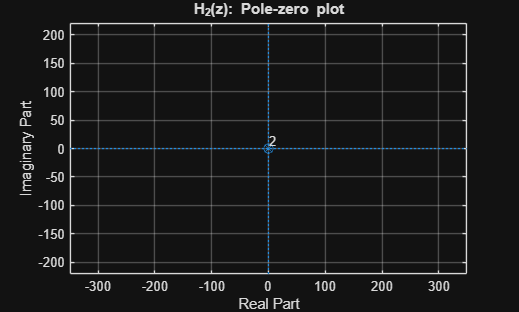

figure;
zplane(B2, A2);
title('H_2(z): Pole-zero plot');
axis equal;
grid on;

if exist('imgDir','var')
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_F24_1_4_pz.png'), 'Resolution', 300);
end

## ROC illustration: |z| > 1/2 (stable, causal)

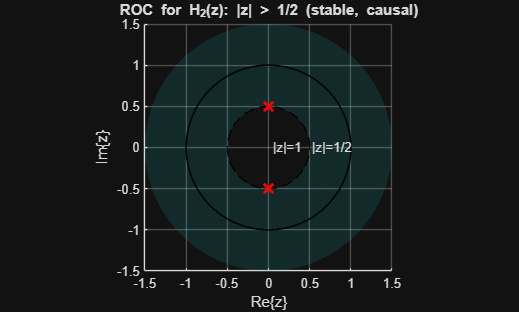

r_pole  = 0.5;        % radius of circle containing poles
r_unit  = 1.0;        % unit circle
r_outer = 1.5;        % outer radius for ROC shading
theta   = linspace(0, 2*pi, 400);

% Circles
x_pole = r_pole * cos(theta);
y_pole = r_pole * sin(theta);
x_unit = r_unit * cos(theta);
y_unit = r_unit * sin(theta);

% Build shaded ROC region: r in [r_pole, r_outer]
[R, T] = meshgrid(linspace(r_pole, r_outer, 60), theta);
Xroc   = R .* cos(T);
Yroc   = R .* sin(T);

figure;
hold on; grid on; axis equal;

% Shade ROC (|z| > 1/2)
surf(Xroc, Yroc, zeros(size(Xroc)), ...
    'EdgeColor', 'none', 'FaceAlpha', 0.15);
view(2);   % 2D view

% Draw |z| = 1/2 and |z| = 1 circles
plot(x_pole, y_pole, 'k--', 'LineWidth', 1.0);   % |z| = 1/2
plot(x_unit, y_unit, 'k-',  'LineWidth', 1.2);   % |z| = 1

% Mark poles and zeros
plot(real(p2), imag(p2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
plot(real(z2), imag(z2), 'bo', 'MarkerSize', 8,  'LineWidth', 1.5);

xlabel('Re\{z\}');
ylabel('Im\{z\}');
title('ROC for H_2(z): |z| > 1/2 (stable, causal)');

text(0.05, 0, '|z|=1',   'FontSize', 10);
text(r_pole+0.03, 0, '|z|=1/2', 'FontSize', 10);

xlim([-r_outer r_outer]);
ylim([-r_outer r_outer]);

if exist('imgDir','var')
    exportgraphics(gcf, fullfile(imgDir, ...
        'DSP_F24_1_4_ROC.png'), 'Resolution', 300);
end

## 1-5) Cascade H3(z) = H(z) * H2(z)

fprintf('\n1-5) Cascade system H3(z) = H(z) H2(z)\n');


1-5) Cascade system H3(z) = H(z) H2(z)



% Cascade polynomials:
B3 = conv(B1, B2);
A3 = conv(A1, A2);

fprintf('Raw cascade (before cancellation):\n');

Raw cascade (before cancellation):


disp('B3 = '); disp(B3);

B3 = 
     4   -12     1    -3



disp('A3 = '); disp(A3);

A3 = 
    1.0000         0    0.2500




% From algebra / solution we know cancellation leads to:
B3_simplified = [4 -12];
A3_simplified = 1;

fprintf('After pole-zero cancellation:\n');

After pole-zero cancellation:


fprintf('H3(z) = 4 - 12 z^{-1}\n');

H3(z) = 4 - 12 z^{-1}


fprintf('Impulse response h3[n] = [4  -12]. (FIR)\n');

Impulse response h3[n] = [4  -12]. (FIR)


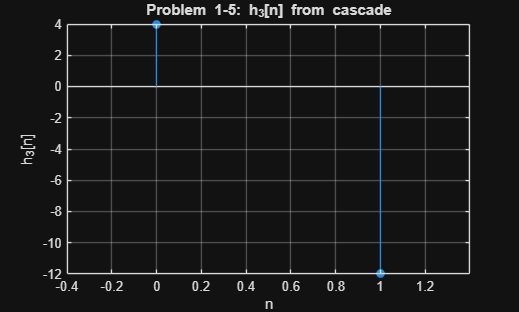


% Plot h3[n]
figure;
stem(0:1, B3_simplified, 'filled'); grid on;
xlabel('n'); ylabel('h_3[n]');
title('Problem 1-5: h_3[n] from cascade');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F24_1_Cascade_h3.png'), 'Resolution', 300);

## Problem 2 — Sampling, Aliasing and Analog AA-Filter

fprintf('\n=== Problem 2 ===\n');


=== Problem 2 ===



A1 = 3;   F1 = 200;   % Hz
A2 = 1.5; F2 = 750;   % Hz


## 2-1) Minimum sampling frequency (Nyquist)

Fmax = max(F1, F2);
Fs_min = 2*Fmax;

fprintf('\n2-1) Minimum sampling frequency (Nyquist)\n');


2-1) Minimum sampling frequency (Nyquist)


fprintf('F_max = %.1f Hz => F_s,min = %.1f Hz\n', Fmax, Fs_min);

F_max = 750.0 Hz => F_s,min = 1500.0 Hz


## 2-2) Aliasing at Fs = 1000 Hz

Fs = 1000;
Nyquist = Fs/2;

fprintf('\n2-2) Aliasing check at Fs = %.1f Hz\n', Fs);


2-2) Aliasing check at Fs = 1000.0 Hz


fprintf('Nyquist = Fs/2 = %.1f Hz\n', Nyquist);

Nyquist = Fs/2 = 500.0 Hz


fprintf('F1 = %.1f Hz < Nyquist => no alias\n', F1);

F1 = 200.0 Hz < Nyquist => no alias


fprintf('F2 = %.1f Hz > Nyquist => aliasing occurs\n', F2);

F2 = 750.0 Hz > Nyquist => aliasing occurs



F_alias = F2 - 2*(F2 - Nyquist);   % single-fold formula
fprintf('Aliased frequency of 750 Hz tone: F_alias = %.1f Hz\n', F_alias);

Aliased frequency of 750 Hz tone: F_alias = 250.0 Hz


## 2-3) Spectrum of sampled signal (Fs = 1000 Hz, N = 1e5)

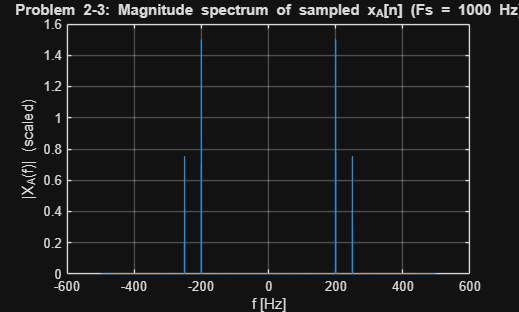

N = 1e5;
Ts = 1/Fs;
n = 0:N-1;
t = n*Ts;

xA = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);

XA   = fft(xA);
XA_s = fftshift(XA)/N;
f = (-N/2:N/2-1)*(Fs/N);

figure;
plot(f, abs(XA_s), 'LineWidth', 1.0); grid on;
xlabel('f [Hz]'); ylabel('|X_A(f)| (scaled)');
title('Problem 2-3: Magnitude spectrum of sampled x_A[n] (Fs = 1000 Hz)');
xlim([-600 600]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F24_2_Spectrum_Aliased.png'), 'Resolution', 300);

## 2-4) 4th-order Butterworth AA-filter (analog)

Fp = 350;                 % Hz (passband edge)
Omegap = 2*pi*Fp;         % rad/s

% 4th-order normalized prototype (3 dB) from table:
B_proto = 1;
A_proto = [1 2.6131 3.4142 2.6131 1];

% Low-pass frequency scaling to desired cutoff:
[B_AA, A_AA] = lp2lp(B_proto, A_proto, Omegap);

fprintf('\n2-4) Analog AA-filter (4th-order Butterworth)\n');


2-4) Analog AA-filter (4th-order Butterworth)


fprintf('Prototype: H_p(s) = 1 / (s^4 + 2.6131 s^3 + 3.4142 s^2 + 2.6131 s + 1)\n');

Prototype: H_p(s) = 1 / (s^4 + 2.6131 s^3 + 3.4142 s^2 + 2.6131 s + 1)


fprintf('Scaled cutoff at F_p = %.1f Hz\n', Fp);

Scaled cutoff at F_p = 350.0 Hz


## 2-5) Magnitude of AA-filter vs F (Hz)

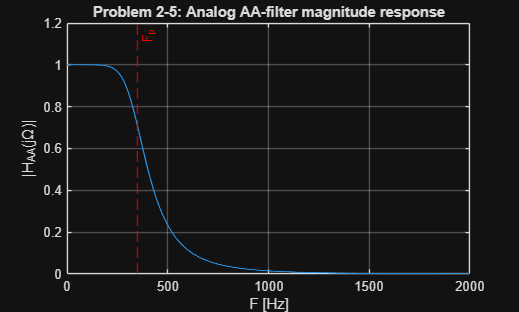

Fmax_plot = 2000;                     % Hz
F_vec = linspace(0, Fmax_plot, 2000);
Omega_vec = 2*pi*F_vec;

H_aa = freqs(B_AA, A_AA, Omega_vec);

figure;
plot(F_vec, abs(H_aa), 'LineWidth', 1.0); grid on;
xlabel('F [Hz]'); ylabel('|H_{AA}(j\Omega)|');
title('Problem 2-5: Analog AA-filter magnitude response');
xline(Fp, '--r', 'F_p');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F24_2_AA_Filter_Magnitude.png'), 'Resolution', 300);

## Problem 3 — Sampling Criteria, Discrete Filter, Min-Phase / All-Pass

fprintf('\n=== Problem 3 ===\n');


=== Problem 3 ===


## 3-1) Sampling criterion for Omega_max = 200 rad/s

Omega_max_1 = 200;   % rad/s

Omega_s_list = [200 400 500];  % rad/s

fprintf('\n3-1) Sampling for Omega_max = 200 rad/s\n');


3-1) Sampling for Omega_max = 200 rad/s


for Os = Omega_s_list
    ok = Os >= 2*Omega_max_1;
    fprintf('Omega_s = %3d rad/s => Nyquist bound = %3d rad/s => %s\n', ...
        Os, 2*Omega_max_1, tern(ok,'OK','NOT OK'));
end

Omega_s = 200 rad/s => Nyquist bound = 400 rad/s => NOT OK
Omega_s = 400 rad/s => Nyquist bound = 400 rad/s => OK
Omega_s = 500 rad/s => Nyquist bound = 400 rad/s => OK


## 3-2) New Omega_max = 250 rad/s

Omega_max_2 = 250;   % rad/s

fprintf('\n3-2) Sampling for Omega_max = 250 rad/s\n');


3-2) Sampling for Omega_max = 250 rad/s


for Os = Omega_s_list
    ok = Os >= 2*Omega_max_2;
    fprintf('Omega_s = %3d rad/s => Nyquist bound = %3d rad/s => %s\n', ...
        Os, 2*Omega_max_2, tern(ok,'OK','NOT OK'));
end

Omega_s = 200 rad/s => Nyquist bound = 500 rad/s => NOT OK
Omega_s = 400 rad/s => Nyquist bound = 500 rad/s => NOT OK
Omega_s = 500 rad/s => Nyquist bound = 500 rad/s => OK


## 3-3) Discrete filter y[n] = 0.5 x[n-1] + 0.7 x[n]

% Impulse response:
% h[0] = 0.7
% h[1] = 0.5
% h[n] = 0 otherwise

h_filt = [0.7 0.5];
fprintf('\n3-3) FIR filter h[n] = [0.7 0.5]\n');


3-3) FIR filter h[n] = [0.7 0.5]


fprintf('Causal and stable (finite-length impulse response).\n');

Causal and stable (finite-length impulse response).


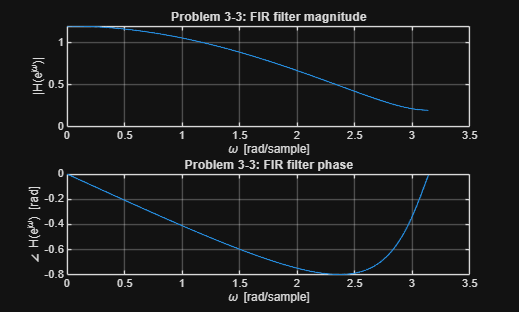


% Frequency response
Nw = 1024;
[Hf, w] = freqz(h_filt, 1, Nw);

figure;
subplot(2,1,1);
plot(w, abs(Hf), 'LineWidth', 1.0); grid on;
xlabel('\omega [rad/sample]'); ylabel('|H(e^{j\omega})|');
title('Problem 3-3: FIR filter magnitude');

subplot(2,1,2);
plot(w, unwrap(angle(Hf)), 'LineWidth', 1.0); grid on;
xlabel('\omega [rad/sample]'); ylabel('\angle H(e^{j\omega}) [rad]');
title('Problem 3-3: FIR filter phase');

exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F24_3_FIR_MagPhase.png'), 'Resolution', 300);

## 3-4) Factorization H(z) = H_min(z) * H_ap(z)

% H(z) = ((1 + 3 z^-1)(1 - 1/2 z^-1)) / (z^-1 (1 + 1/3 z^-1))
%
% One valid factorization:
% H_ap(z)   = G * (1 + 3 z^-1) / (1 + 1/3 z^-1)
% H_min(z)  = (1/G) * (1 - 1/2 z^-1) / z^-1
% with G ≠ 0 (often choose G = 1 for simplicity).

fprintf('\n3-4) Minimum-phase and all-pass factorization\n');


3-4) Minimum-phase and all-pass factorization


fprintf('Choose G = 1:\n');

Choose G = 1:


fprintf('  H_min(z) = (1 - 0.5 z^{-1}) / z^{-1}\n');

  H_min(z) = (1 - 0.5 z^{-1}) / z^{-1}


fprintf('  H_ap(z)  = (1 + 3 z^{-1}) / (1 + (1/3) z^{-1})\n');

  H_ap(z)  = (1 + 3 z^{-1}) / (1 + (1/3) z^{-1})


fprintf('H_ap(z) has zeros and poles mirrored about the unit circle (all-pass).\n');

H_ap(z) has zeros and poles mirrored about the unit circle (all-pass).


fprintf('H_min(z) has all zeros inside the unit circle (minimum phase).\n');

H_min(z) has all zeros inside the unit circle (minimum phase).


## Problem 4 — BLT IIR Bandstop Butterworth Design

fprintf('\n=== Problem 4 ===\n');


=== Problem 4 ===



Fs = 5000;           % Hz
Ts = 1/Fs;

% Digital edge frequencies (in Hz, from spec):
fpL = 45.0;  fpH = 55.5;
fsL = 48.0;  fsH = 52.1;

Ap  = 3;     % dB
As  = 20;    % dB

fprintf('\nSpecifications:\n');


Specifications:


fprintf('  F_s = %.1f Hz\n', Fs);

  F_s = 5000.0 Hz


fprintf('  f_pL = %.2f Hz, f_pH = %.2f Hz\n', fpL, fpH);

  f_pL = 45.00 Hz, f_pH = 55.50 Hz


fprintf('  f_sL = %.2f Hz, f_sH = %.2f Hz\n', fsL, fsH);

  f_sL = 48.00 Hz, f_sH = 52.10 Hz


fprintf('  A_p  = %.1f dB, A_s = %.1f dB\n', Ap, As);

  A_p  = 3.0 dB, A_s = 20.0 dB


## 4-1a) Prewarp digital edges to analog Omega (rad/s)

prewarp = @(F) 2*Fs * tan(pi*F/Fs);

Omega_pL = prewarp(fpL);
Omega_pH = prewarp(fpH);
Omega_sL = prewarp(fsL);
Omega_sH = prewarp(fsH);

fprintf('\n4-1a) Prewarped edge frequencies (rad/s):\n');


4-1a) Prewarped edge frequencies (rad/s):


fprintf('  Omega_pL = %.3e\n', Omega_pL);

  Omega_pL = 2.828e+02


fprintf('  Omega_pH = %.3e\n', Omega_pH);

  Omega_pH = 3.489e+02


fprintf('  Omega_sL = %.3e\n', Omega_sL);

  Omega_sL = 3.017e+02


fprintf('  Omega_sH = %.3e\n', Omega_sH);

  Omega_sH = 3.275e+02


## 4-1b) Prototype order (Butterworth)

% For a Butterworth LP prototype:
%   epsilon^2 = 10^(Ap/10) - 1
%   (Omega_s/Omega_p)^(2n) = (10^(As/10) - 1)/(10^(Ap/10) - 1)
%
% In the bandstop mapping we end up with an effective frequency ratio v_s;
% here we follow the solution sheet and just show how to compute n
% given v_s.

epsilon2 = 10^(Ap/10) - 1;
epsilon  = sqrt(epsilon2);

% Effective frequency ratio from solution (just stored here):
v_s = 2.56;   % from the official solution (approx)

n_est = log10((10^(As/10)-1)/(10^(Ap/10)-1)) / (2*log10(v_s));
n_min = ceil(n_est);

fprintf('\n4-1b) Butterworth prototype order\n');


4-1b) Butterworth prototype order


fprintf('  epsilon^2 = %.3f, epsilon = %.3f\n', epsilon2, epsilon);

  epsilon^2 = 0.995, epsilon = 0.998


fprintf('  Using v_s = %.2f => n_est = %.3f => n_min = %d\n', v_s, n_est, n_min);

  Using v_s = 2.56 => n_est = 2.447 => n_min = 3



% We take n = 3 from the solution:
n = 3;



## 4-1c) Prototype H_proto(s) for n = 3

% From table: H_proto(s) = 1 / (s^3 + 2 s^2 + 2 s + 1)
B_proto = 1;
A_proto = [1 2 2 1];

fprintf('\n4-1c) Prototype H_proto(s) = 1 / (s^3 + 2 s^2 + 2 s + 1)\n');


4-1c) Prototype H_proto(s) = 1 / (s^3 + 2 s^2 + 2 s + 1)


## 4-2a) Analog bandstop H_BS(s) via lp2bs

Omega0 = sqrt(Omega_sL * Omega_sH);      % center angular frequency
B_bw   = Omega_pH - Omega_pL;           % bandwidth

[B_BS, A_BS] = lp2bs(B_proto, A_proto, Omega0, B_bw);

fprintf('\n4-2a) Analog bandstop H_BS(s) obtained via lp2bs().\n');


4-2a) Analog bandstop H_BS(s) obtained via lp2bs().


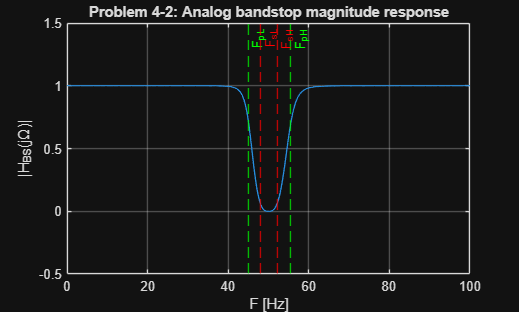


% Analog magnitude response
Omega_plot = linspace(0, 3000, 4000);      % rad/s
H_bs = freqs(B_BS, A_BS, Omega_plot);

figure;
plot(Omega_plot/(2*pi), abs(H_bs), 'LineWidth', 1.0); grid on;
xlabel('F [Hz]');
ylabel('|H_{BS}(j\Omega)|');
title('Problem 4-2: Analog bandstop magnitude response');
hold on;
xline(Omega_pL/(2*pi), '--g', 'F_{pL}');
xline(Omega_pH/(2*pi), '--g', 'F_{pH}');
xline(Omega_sL/(2*pi), '--r', 'F_{sL}');
xline(Omega_sH/(2*pi), '--r', 'F_{sH}');
xlim([0 100]);
ylim([-0.5 1.5]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F24_4_Analog_Bandstop_Magnitude.png'), 'Resolution', 300);

## 4-3a) Digital bandstop H_BS(z) via Bilinear Transform

[Bz, Az] = bilinear(B_BS, A_BS, Fs);


fprintf('\n4-3a) Digital IIR bandstop H_BS(z) via bilinear().\n');


4-3a) Digital IIR bandstop H_BS(z) via bilinear().


fprintf('Numerator Bz:\n'); disp(Bz);

Numerator Bz:
    0.9869   -5.9097   14.7567  -19.6678   14.7567   -5.9097    0.9869



fprintf('Denominator Az:\n'); disp(Az);

Denominator Az:
    1.0000   -5.9618   14.8215  -19.6675   14.6917   -5.8578    0.9740



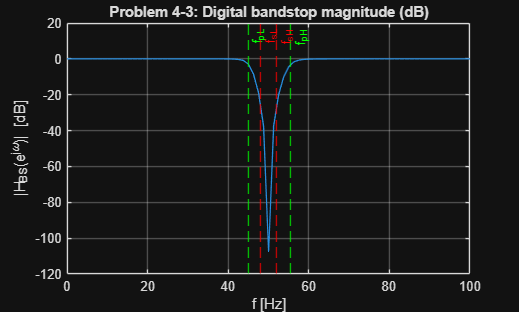


% Digital magnitude in dB vs frequency (Hz)
f_dig = linspace(0, Fs/2, 2000);
[Hdig, ~] = freqz(Bz, Az, f_dig, Fs);
MagdB = 20*log10(abs(Hdig));

figure;
plot(f_dig, MagdB, 'LineWidth', 1.0); grid on;
xlabel('f [Hz]');
ylabel('|H_{BS}(e^{j\omega})| [dB]');
title('Problem 4-3: Digital bandstop magnitude (dB)');
hold on;
xline(fpL, '--g', 'f_{pL}');
xline(fpH, '--g', 'f_{pH}');
xline(fsL, '--r', 'f_{sL}');
xline(fsH, '--r', 'f_{sH}');
xlim([0 100]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_Exam_F24_4_Digital_Bandstop_Magnitude_dB.png'), 'Resolution', 300);

## 4-3b) Attenuation at specified edge frequencies

f_edges = [fpL fsL 50 fsH fpH];
[H_edges, ~] = freqz(Bz, Az, f_edges, Fs);
Att_edges_dB = 20*log10(abs(H_edges));

fprintf('\n4-3b) Attenuation at key frequencies:\n');


4-3b) Attenuation at key frequencies:


disp(table(f_edges(:), Att_edges_dB(:), ...
    'VariableNames', {'Frequency_Hz','Magnitude_dB'}));

    Frequency_Hz    Magnitude_dB
    ____________    ____________

          45          -2.9213   
          48          -24.519   
          50          -105.98   
        52.1          -24.521   
        55.5          -3.0842   




fprintf('\nCheck against specs: A_p <= 3 dB, A_s >= 20 dB.\n');


Check against specs: A_p <= 3 dB, A_s >= 20 dB.


fprintf('You should see ~3 dB in passbands and > 20 dB in stopband edges.\n');

You should see ~3 dB in passbands and > 20 dB in stopband edges.


## Helper function: ternary string (for inline printing)

function out = tern(cond, sTrue, sFalse)
    if cond
        out = sTrue;
    else
        out = sFalse;
    end
end